# PlatoonPlots

## BASE CENERI BOX 80-20 BF 1.46 W 22/23 FIG. 6

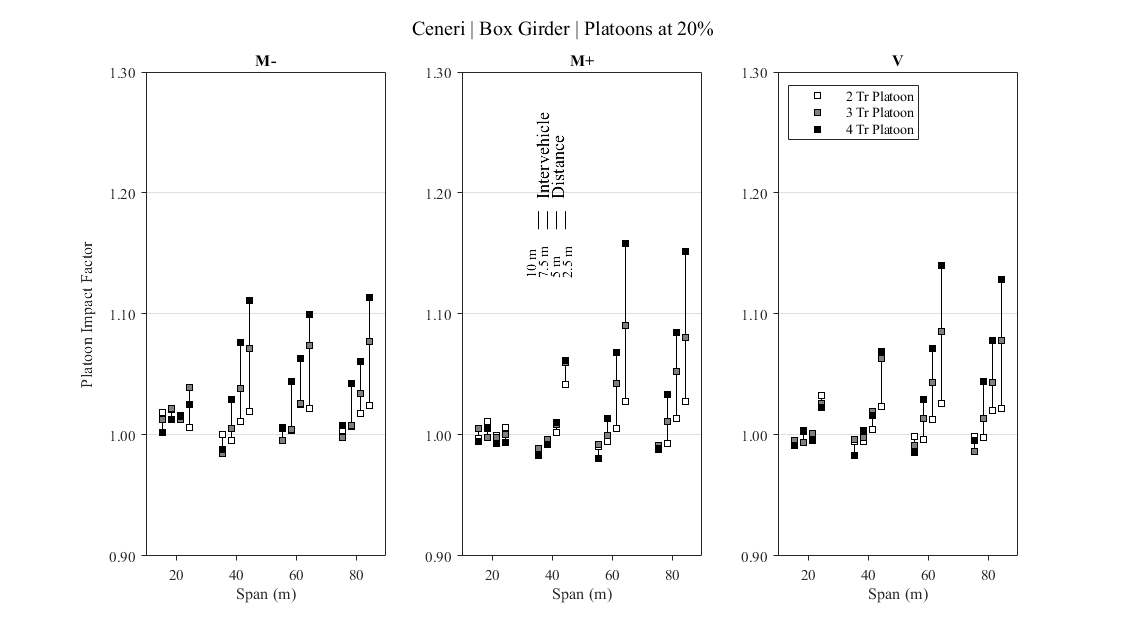

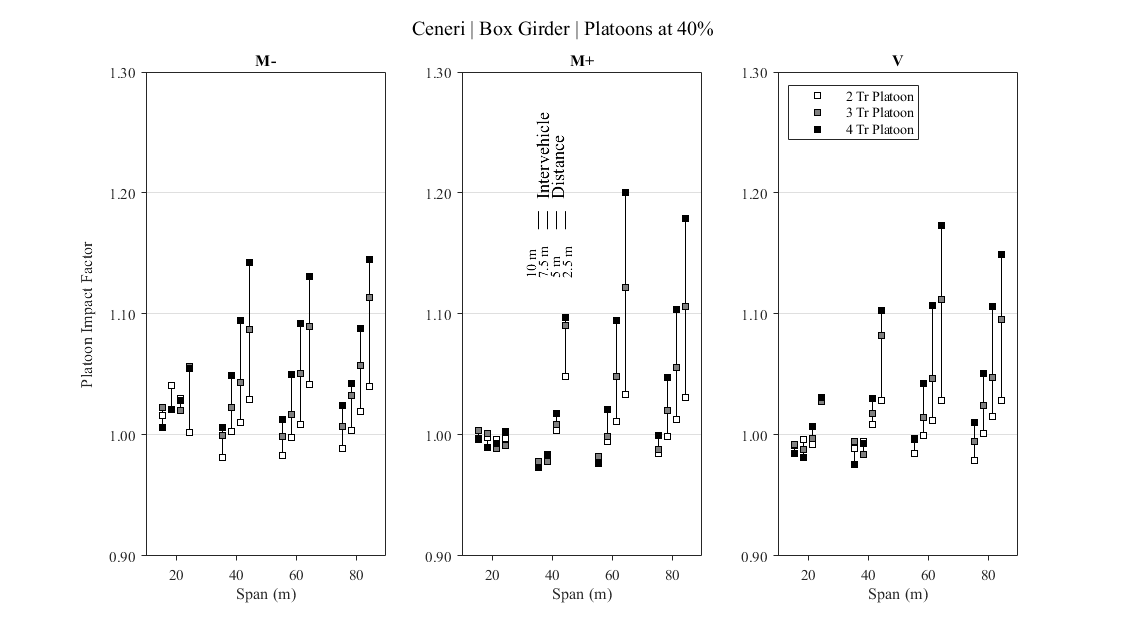


% Initial Commands
clear, clc, close all

% Plot toggles (1 through 4 are 2.5m 5m 7.5m 10m) (use j)
MATPlots = [1 2 3 4];

Section = 'Box'; % Box, Twin, TwinRed, TwinExp, TwinConc
Config = 'Mo';   % Bi, Mo
Dist = 'ExFast'; % Split, Stand, ExFast, ExSlow

Loc = 'Ceneri2017'; % Set Location

% Set Action Effects
AE{1} = 'Mn'; AE{2} = 'Mp'; AE{3} = 'V';
% Set Titles
Title{1} = 'M-'; Title{2} = 'M+'; Title{3} = 'V';

% Set Platoon Size, (use w)
PlatSize{1} = 'S2'; PlatSize{2} = 'M3'; PlatSize{3} = 'L4';
PlatSizeNum = 2:4;

% Set Platoon Rate, (use r)
PlatRate{1} = 'L20'; PlatRate{2} = 'H40';
PlatRateNum = [0.2 0.4];

% Set Plot Parameters
% Set Intervehicle Distance
IVD{1} = 'SMax'; IVD{2} = 'MSMax'; IVD{3} = 'MLMax'; IVD{4} = 'LMax';
%IVD{1} = 'SMean'; IVD{2} = 'MSMean'; IVD{3} = 'MLMean'; IVD{4} = 'LMean';
IVDnum = 2.5:2.5:10;

% Set Colors - could use linspecer and change
Col{1} = [0.9100 0.4100 0.1700]; Col{2} = [0.2745 0.6863 0.8902];
Col{3} = [0.2745 0.8314 0.1922]; Col{4} = [0.6 0.6 0.6];

Col{1} = [1 1 1]; Col{2} = [0.5 0.5 0.5];
Col{3} = [0 0 0];

% Set Symbols
Sym{1} = 's'; Sym{2} = 's'; Sym{3} = 's'; 

%Sym{1} = 'x'; Sym{2} = '*'; Sym{3} = '_'; 


% Set Plot Size Parameters
MSize = 5; LWid = 1; Xmin = 20;

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);

clear J
% Legend labels
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon';

% PLAT
load('PLATResultsx.mat')

% X Data
X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Ceneri',Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            %Minb = 2; Maxb = 0.5;
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
                
                % Save smart to lead in Platoon Confidence
                if r == 1 & w == 3 & j == 1
                    SimPts.(AE{i}) = Y.(IVD{j})./Y.BaseMax;
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([1 2 3]),'FontName','Times','Location','northwest');
        end
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
        All = All(2:4,1:3);
        Track.Base.(AE{i}) = mean(mean(All));
        
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])
    
end

## BASE CENERI BOX 80-20 BF 1.46 W 22/23  FIG. 6

## DENGES EXPLORATION - DENGES BOX 80-20 BF 1.46 W 22/23  FIG. 8

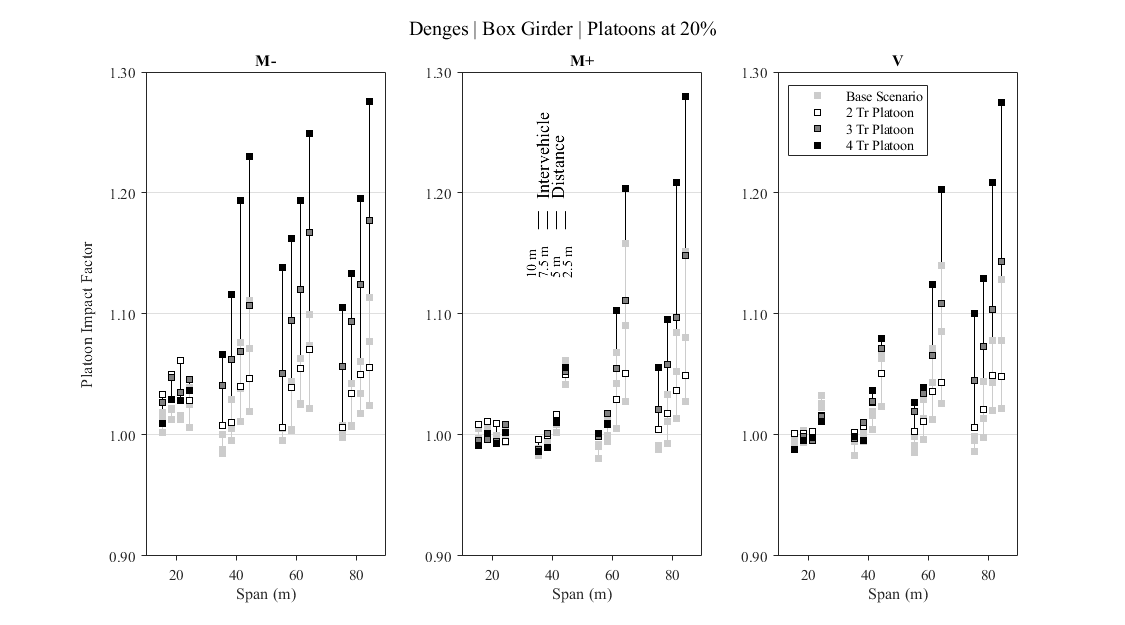

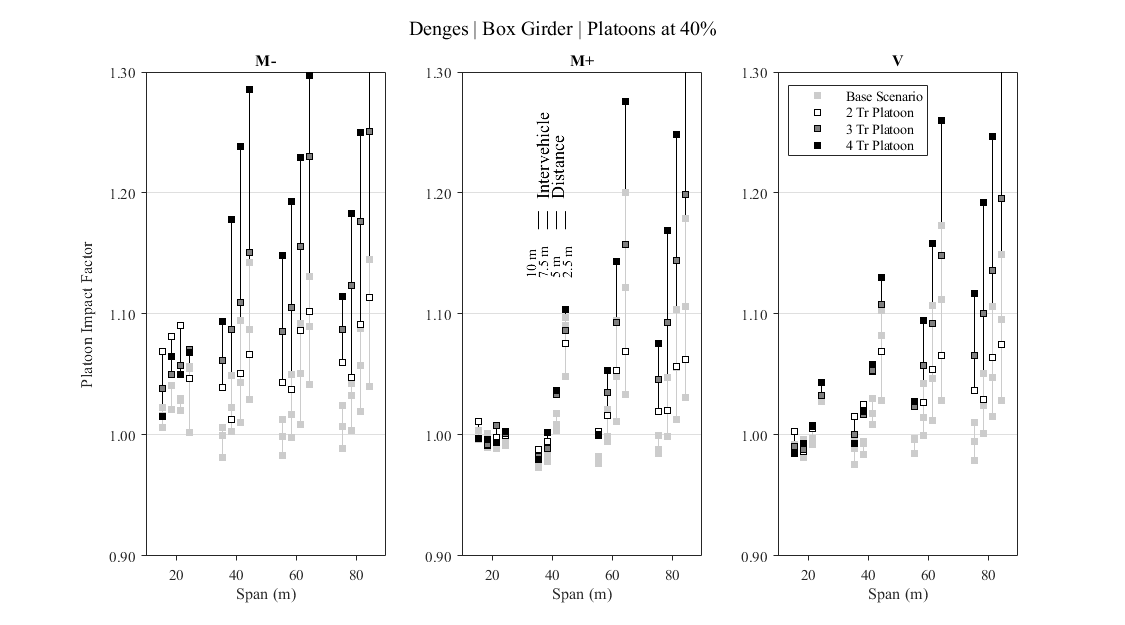


close all
% PLAT
load('PLATResultsx.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';
Loc2 = 'Denges2017';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Loc2)
    temp = Loc2; clear Loc2; [Loc2{1:3}] = deal(temp);
end

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Denges',Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end 
        
        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc2{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        All = All(2:4,1:3);
        Track.Denges.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## DENGES EXPLORATION - DENGES BOX 80-20 BF 1.46 W 22/23   FIG. 8

## TWIN EXPLORATION - CENERI TWIN 80-20 BF 1.46 W 22/23  FIG. 7

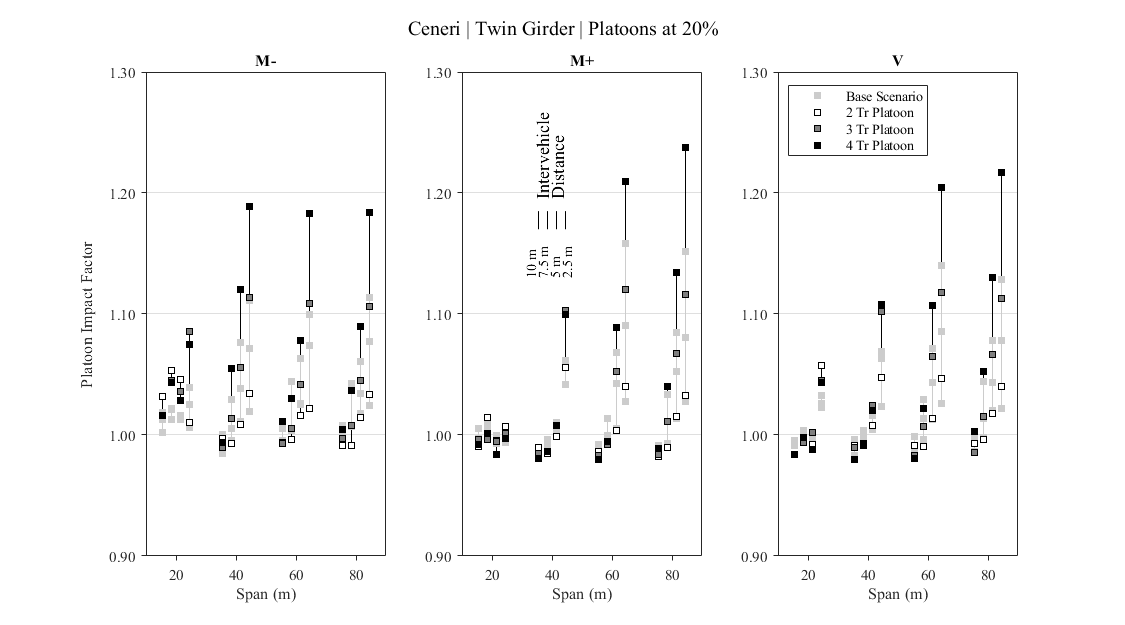

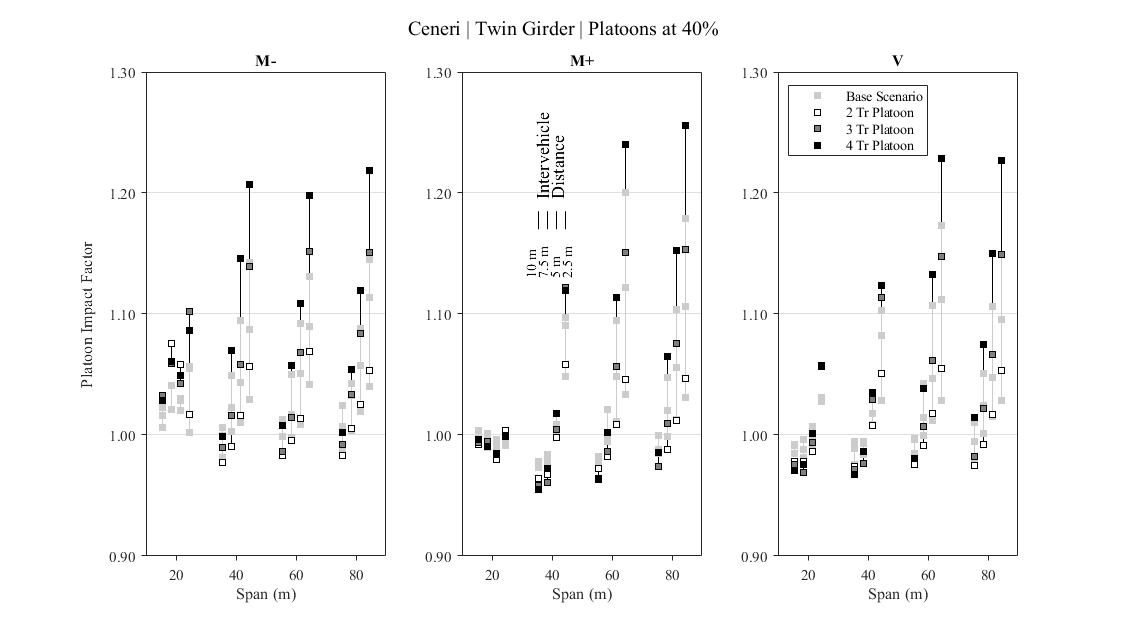

close all
% PLAT
load('PLATResultsx.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';

Section2 = 'Twin';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Section2)
    temp = Section2; clear Section2; [Section2{1:3}] = deal(temp);
end

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Ceneri',Section2{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end 
        
        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section2{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        All = All(2:4,1:3);
        Track.Twin.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## TWIN EXPLORATION - CENERI TWIN 80-20 BF 1.46 W 22/23  FIG. 7

## 96-4 EXPLORATION - CENERI BOX 96-4 BF 1.46 W 22/23

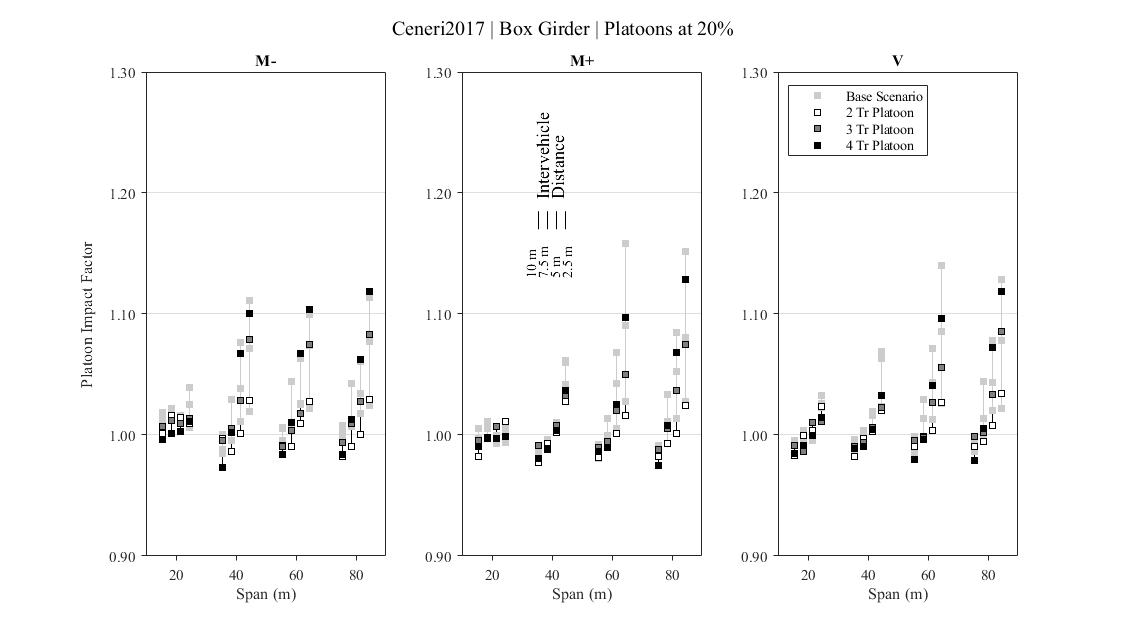

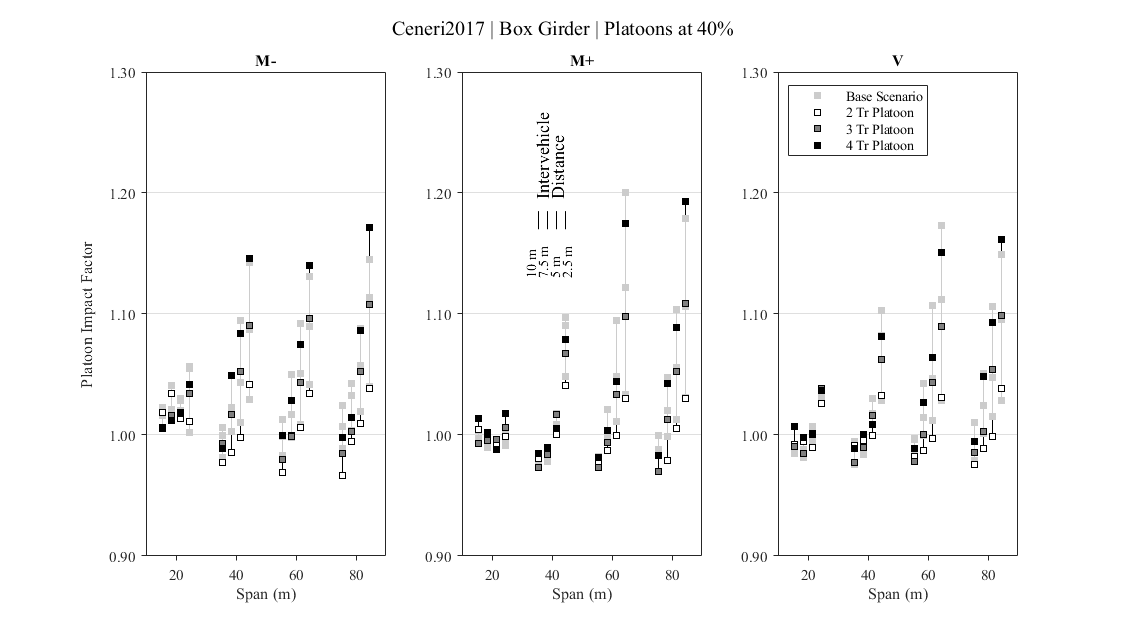

close all
% PLAT
load('PLATResultsx.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';

Dist2 = 'Stand';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Dist2)
    temp = Dist2; clear Dist2; [Dist2{1:3}] = deal(temp);
end

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%',Loc{1},Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end 
        
        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist2{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        All = All(2:4,1:3);
        Track.Stand.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## 96-4 EXPLORATION - CENERI BOX 96-4 BF 1.46 W 22/23

## BF EXPLORATION - CENERI BOX 80-20 BF 1.00 W 22/23

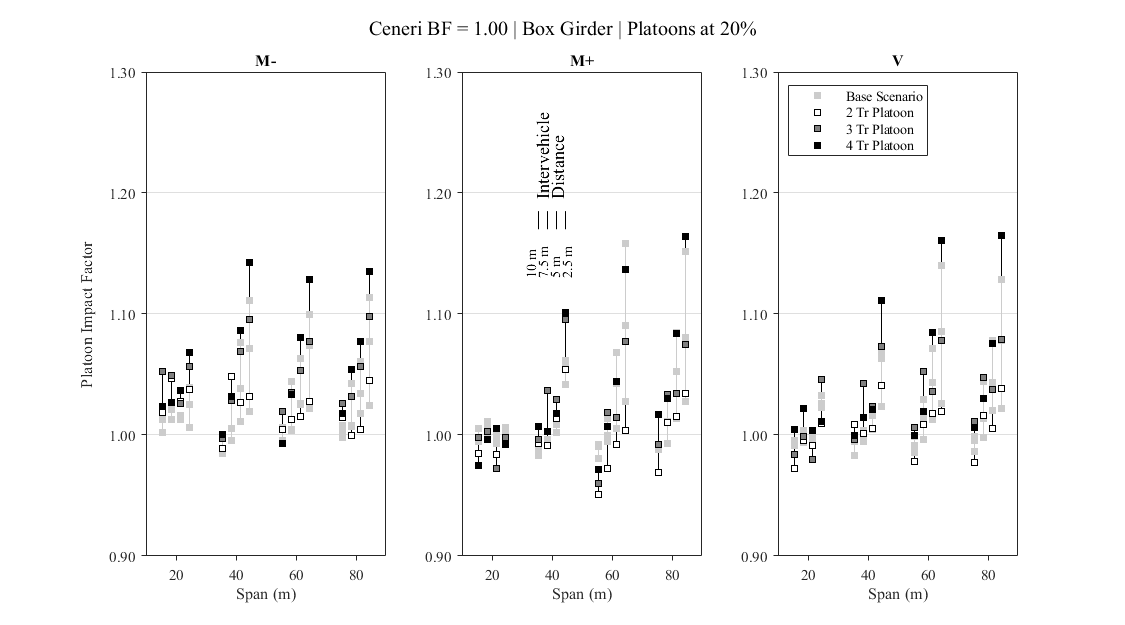

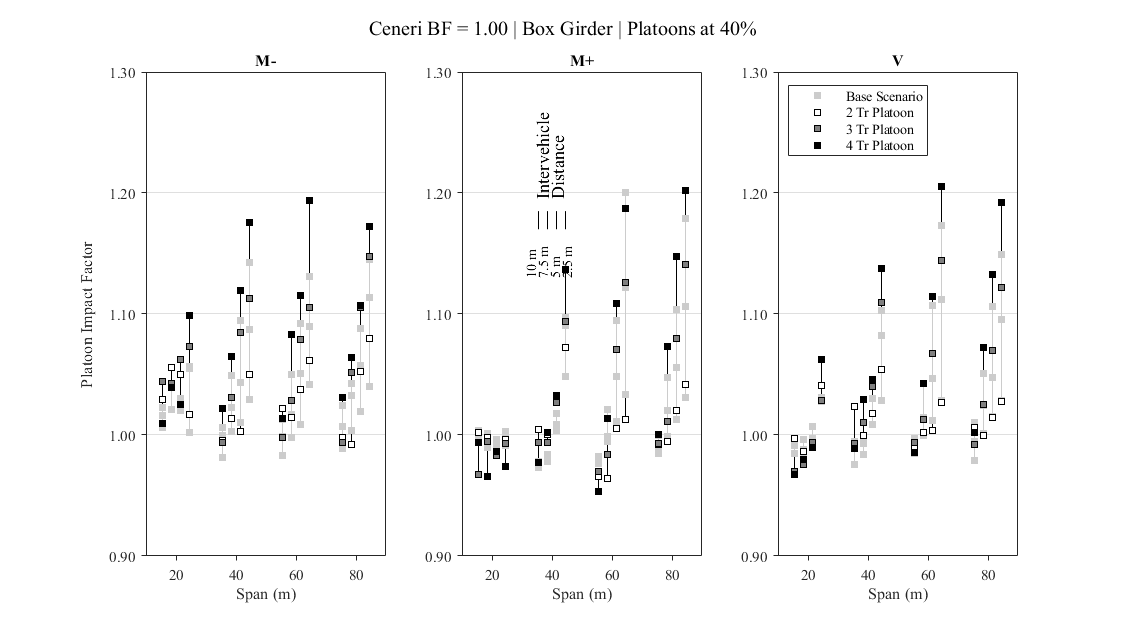

close all
% PLAT

load('PLATResultsBunch.mat')
PLATx = PLAT;
load('PLATResultsx.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';
Section = 'Box';
Dist = 'ExFast';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Ceneri BF = 1.00',Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end 
        
        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLATx.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        All = All(2:4,1:3);
        Track.BFL.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## BF EXPLORATION - CENERI BOX 80-20 BF 1.00 W 22/23

## BF EXPLORATION - CENERI BOX 80-20 BF 1.92 W 22/23

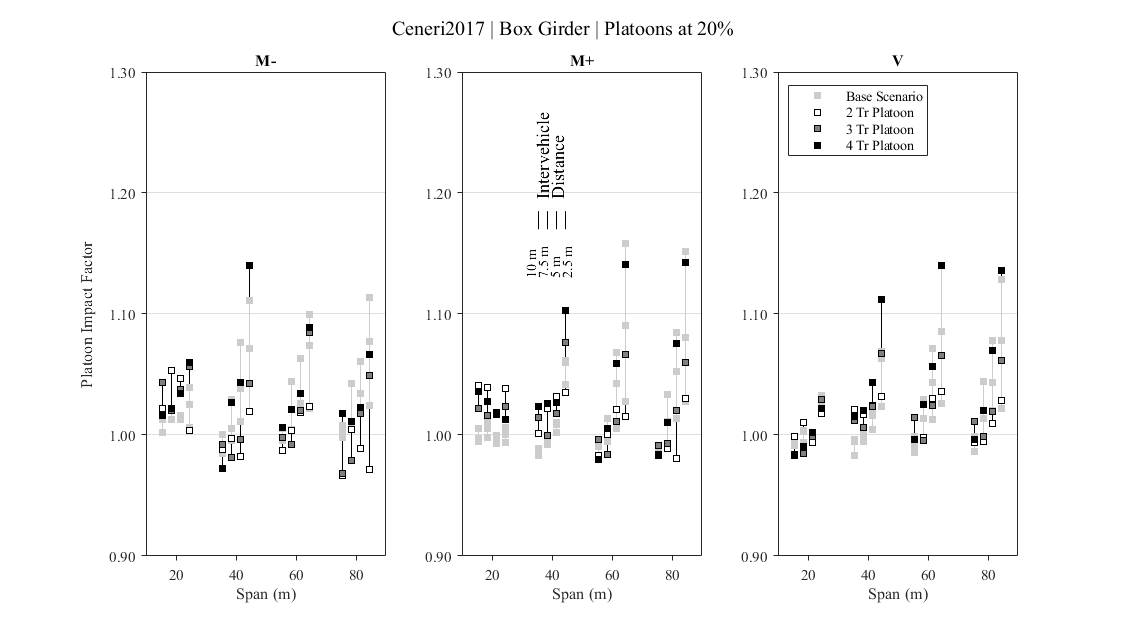

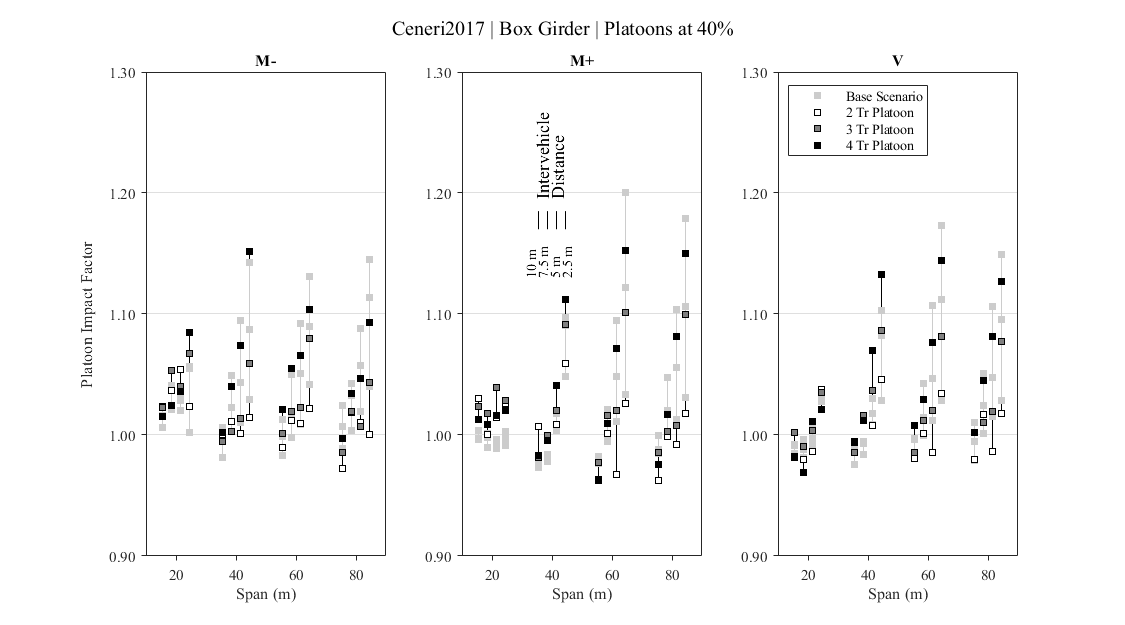

close all
% PLAT

load('PLATResultsBunch2.mat')
PLATx = PLAT;
load('PLATResultsx.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';
Section = 'Box';
Dist = 'ExFast';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%',Loc{1},Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end 
        
        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLATx.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        All = All(2:4,1:3);
        Track.BFH.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## BF EXPLORATION - CENERI BOX 80-20 BF 1.92 W 22/23

## NO TYPE 22, 23 EXPLORATION - CENERI BOX 80-20 BF 1.46 W/U 22/23   FIG. 9

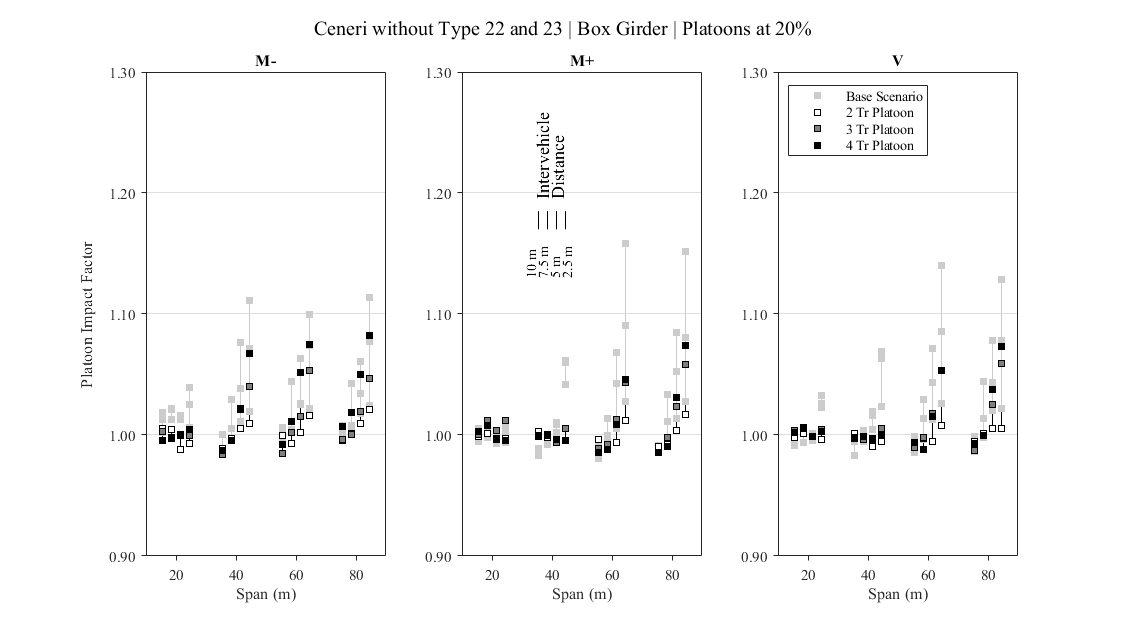

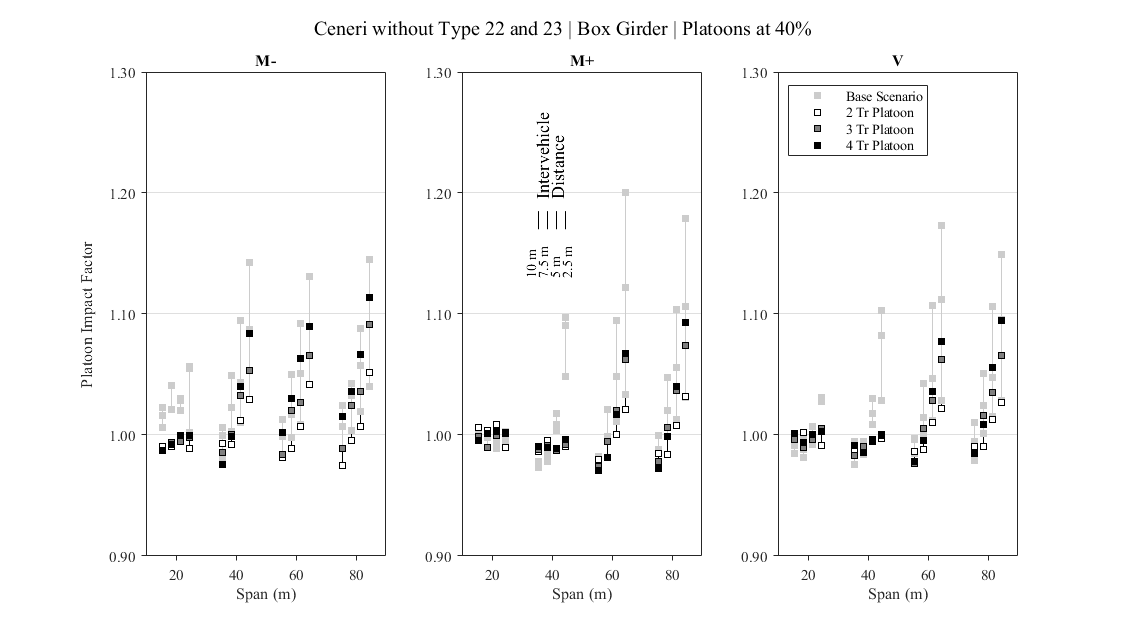

close all

% PLAT
load('PLATResultsx.mat')
PLAT2 = PLAT;
load('PLATResultsxNoCompact.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Base Scenario';

% Set Location
Loc = 'Ceneri2017';
Loc2 = 'Denges2017';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Loc2)
    temp = Loc2; clear Loc2; [Loc2{1:3}] = deal(temp);
end

X = 20:20:80; X = X';

for r = 1:2 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Ceneri without Type 22 and 23',Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT2.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end

        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                Yx = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        
        All = All(2:4,1:3);
        Track.NoComp.(AE{i}) = mean(mean(All));
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## NO TYPE 22, 23 EXPLORATION - CENERI BOX 80-20 BF 1.46 W/U 22/23   FIG. 9

## NO TYPE 22, 23 EXPLORATION - DENGES BOX 80-20 BF 1.46 W/U 22/23   FIG. 9

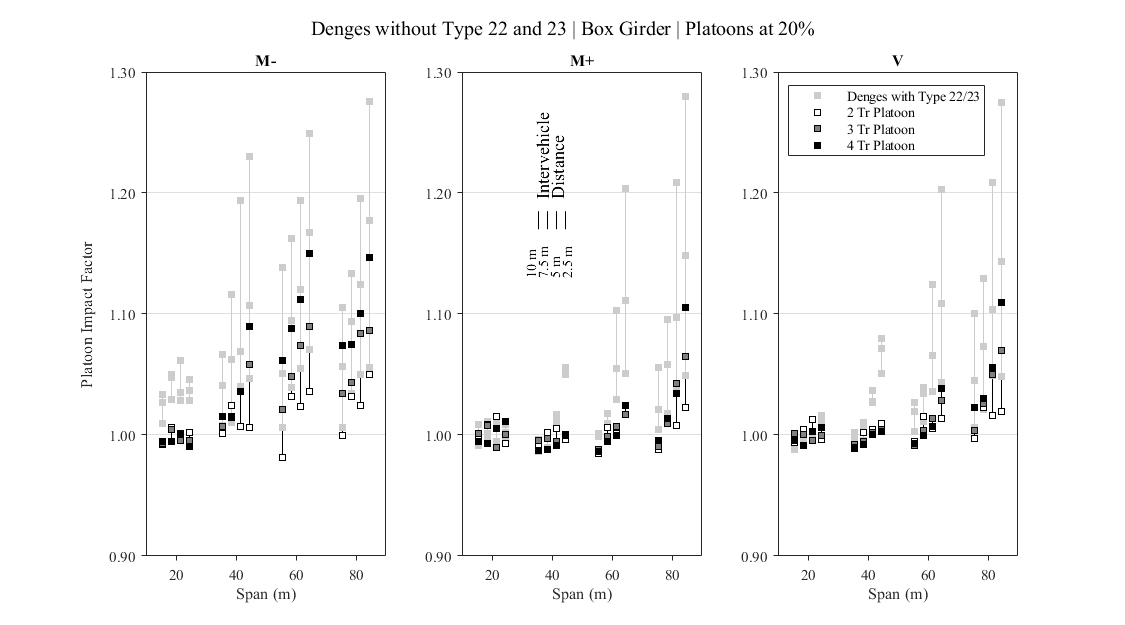


close all

% PLAT
load('PLATResultsx.mat')
PLAT2 = PLAT;
load('PLATResultsxNoCompact.mat')

clear J
% Legend labels 
J{1} = '2 Tr Platoon'; J{2} = '3 Tr Platoon';  J{3} = '4 Tr Platoon'; J{4} = 'Denges with Type 22/23';

% Set Location
Loc = 'Ceneri2017';
Loc2 = 'Denges2017';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Loc2)
    temp = Loc2; clear Loc2; [Loc2{1:3}] = deal(temp);
end

X = 20:20:80; X = X';

for r = 1 % 1 is 20%, 2 is 40%
    
    % Assign Figure Name
    FName = sprintf('%s | %s Girder | Platoons at %i%%','Denges without Type 22 and 23',Section{1},PlatRateNum(r)*100);
    
    % Initialize Figure
    figure('Name',FName,'NumberTitle','off')
    
    for i = 1:3 % for each subplot
        
        % Initialize subplot and get handle for step after
        sp = subplot(1,3,i);
        All = [];
        
        % Set height of subplot as 95% to allow for subplot title
        q = get(sp,'position');
        q(4) = 0.95*q(4);
        set(sp,'position',q);
        
        for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT2.(Section{i}).(Dist{i}).(Loc2{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1 & w == 3
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor',[0.8 0.8 0.8],'MarkerFaceColor',[0.8 0.8 0.8],'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color',[0.8 0.8 0.8],'HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Set tick and grid details
        ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:20:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
        
        % Axis labels
        xlabel('Span (m)','FontName','times')
        
        % Set title
        title(Title{i},'FontName','times')
        
        % get handle of current, set box property to off and remove background color
        a = gca; set(a,'box','off','color','none','FontName','Times');
        % create new, empty axes with box but without ticks
        b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
        % set original axes as active, and link axes in case of zooming
        axes(a); linkaxes([a b]);
        
        % Set axis limits
        ylim([.90 1.3]); xlim([Xmin-10 90])
        if i == 1
            ylabel('Platoon Impact Factor','FontName','Times');
            yh = get(gca,'ylabel'); % handle to the label object
            p = get(yh,'position'); % get the current position property
            p(1) = 0.9*p(1);          % double the distance,
            % negative values put the label below the axis
            set(yh,'position',p)   % set the new position
        end

        All = [];
        
         for j = MATPlots
            for w = 1:3 % 1 2 3 is 2 3 4 truck platoons
                
                % Get Y Data
                Y = PLAT.(Section{i}).(Dist{i}).(Loc2{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                Yx = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
                % Track values for lines later
                All = [All Y.(IVD{j})./Y.BaseMax];
                
                hold on
                if j == 1
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize)
                else
                    plot(X+3*(2.5-j),Y.(IVD{j})./Y.BaseMax,'-s','Marker',Sym{w},'Color','none','MarkerEdgeColor','k','MarkerFaceColor',Col{w},'MarkerSize',MSize,'HandleVisibility','off')
                end
            end
        end
        
        % Get Maxes and mins
        RangeS = [1 4 7 10];
        for j = MATPlots
            Min(:,j) = min(All(:,RangeS(j):RangeS(j)+2),[],2);
            Max(:,j) = max(All(:,RangeS(j):RangeS(j)+2),[],2);
        end
        
        % Plot top/bottom lines
        for j = flip(MATPlots)
            Xp = X+3*(2.5-j);
            for v = 1:4
                b = line([Xp(v) Xp(v)],[Min(v,j) Max(v,j)],'Color','k','HandleVisibility','off');
                uistack(b,'bottom');
            end
        end
        
        % Legend if last subplot
        if i == 3
            legend(J([4 1 2 3]),'FontName','Times','Location','northwest');
        end
        
        if i == 2
            text(33,1.13,'10 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(37,1.13,'7.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(41,1.13,'5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(45,1.13,'2.5 m',"Rotation",90,'FontName','times','FontSize',8.5)
            text(36.5,1.195,'Intervehicle',"Rotation",90,'FontName','times','FontSize',11)
            text(41.5,1.195,'Distance',"Rotation",90,'FontName','times','FontSize',11)
            for j = flip(MATPlots)
                Xp = X+3*(2.5-j);
                for v = 2
                    b = line([Xp(v) Xp(v)],[1.17 1.185],'Color','k','HandleVisibility','off');
                    uistack(b,'bottom');
                end
            end
        end
    end
    
    sgtitle(FName,'FontName','times','FontSize',12)
    set(gcf,'Position',[0 0 900 500])

end

## NO TYPE 22, 23 EXPLORATION - DENGES BOX 80-20 BF 1.46 W/U 22/23   FIG. 9

## REFERENCE PERIOD EXPLORATION - 50k & 2mil

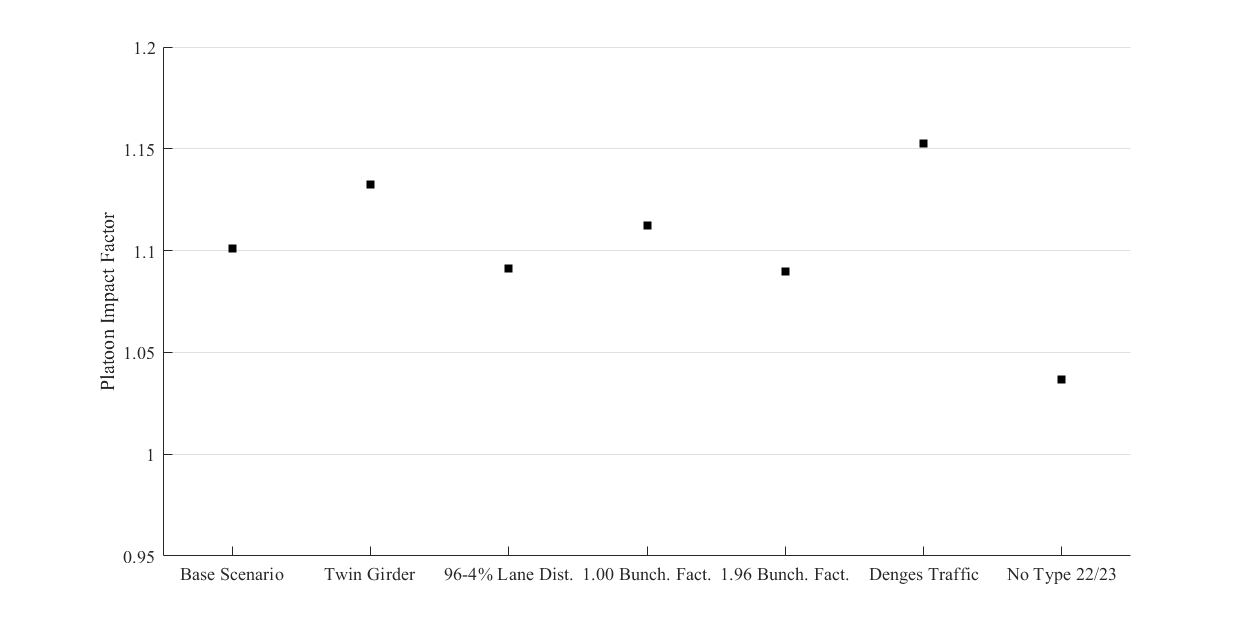

close all

figure

Fns = fieldnames(Track);
%Res = zeros(length(Fns),3);
Res = [];

for v = 1:length(Fns)
    
%     Res(v,1) = [Track.(Fns{v}).Mn];
%     Res(v,2) = [Track.(Fns{v}).Mp];
%     Res(v,3) = [Track.(Fns{v}).V];
    
        Res= [Res Track.(Fns{v}).Mp];

end

%scatter([1 2 3 4 5 6 7],mean(Res,2))
scatter([1:7],Res([1 3 4 5 6 2 7]),'sk','filled')
xticks(1:7)
xticklabels({'Base Scenario' 'Twin Girder' '96-4% Lane Dist.' '1.00 Bunch. Fact.' '1.96 Bunch. Fact.' 'Denges Traffic' 'No Type 22/23'});

ylabel('Platoon Impact Factor','FontName','Times','FontSize',11);

% Set axis limits
ylim([.95 1.2]); xlim([0.5 7.5])
hold on
%fill([0 0 9 9],[0.8 1 1 0.8],[0.7 0.7 0.7])
set(gcf,'Position',[0 0 1000 500])
set(gca,'YGrid','on','FontName','Times','FontSize',11);

## REFERENCE PERIOD EXPLORATION - 50k & 500k & 2mil (legacy)

Next we show the effect of doing 50k instead of 2,000,000

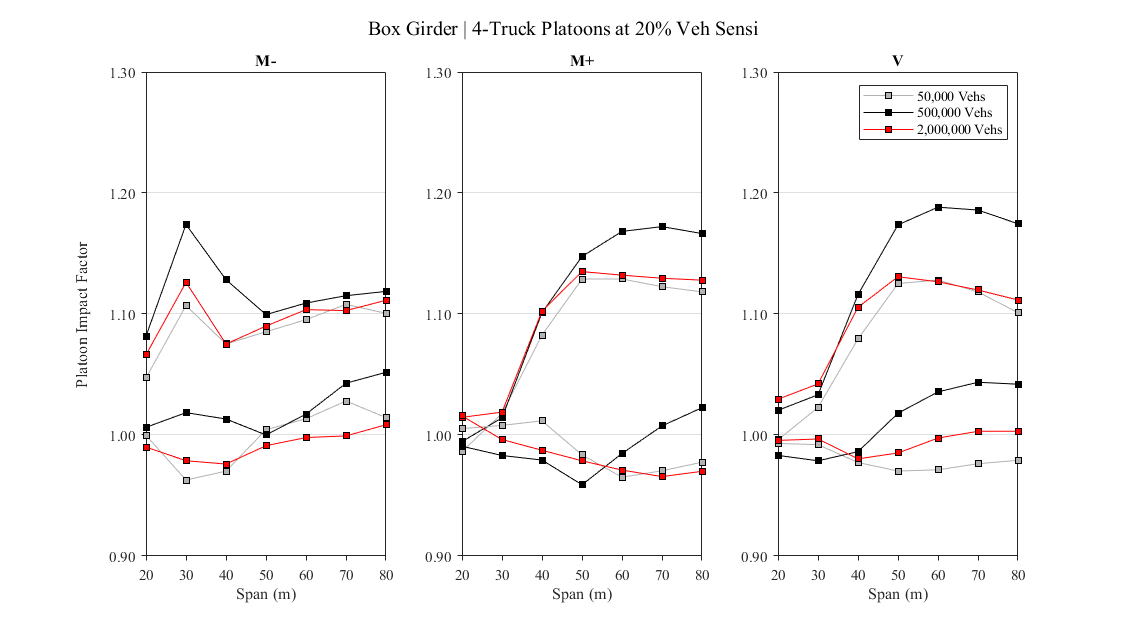

close all

load('PLATResultsx.mat')
PLAT2 = PLAT;
load('PLATVehSensi.mat')

% Set Location
Loc = 'FIFD';
Loc2 = 'FIVD';
Loc4 = 'TWOD';

Loc3 = 'Ceneri2017';

Section = 'Box';

% Convert to cellular if necessary
[Section,AE,Dist,Loc] = Convert2Cells4Plots(Section,AE,Dist,Loc);
if ~iscell(Loc2)
    temp = Loc2; clear Loc2; [Loc2{1:3}] = deal(temp);
end
if ~iscell(Loc3)
    temp = Loc3; clear Loc3; [Loc3{1:3}] = deal(temp);
end
if ~iscell(Loc4)
    temp = Loc4; clear Loc4; [Loc4{1:3}] = deal(temp);
end

X = 10:10:80; X = X';

clear J
% Legend labels
%J{1} = '2.5 m IVD | 50,000 Vehs'; J{2} = '2.5 m IVD | 2,000,000 Vehs';  J{3} = '10 m IVD | 50,000 Vehs'; 
%J{4} = '10 m IVD | 2,000,000 Vehs';

J{1} = '50,000 Vehs'; J{2} = '500,000 Vehs';  J{3} = '2,000,000 Vehs'; 
%J{4} = '10 m IVD | 2,000,000 Vehs';

% Initialize Figure
figure('Name','NumVehSensitivity','NumberTitle','off')
    
for r = 1 % 1 is 20%, 2 is 40%
    
    for w = 3 % 1 2 3 is 2 3 4 truck platoons
        
        % Assign Figure Name
        try
            FName = sprintf('%s Girder | %i-Truck Platoons at %i%% Veh Sensi',Section,w+1,PlatRateNum(r)*100);
        catch
            FName = sprintf('%s Girder | %i-Truck Platoons at %i%% Veh Sensi',Section{1},w+1,PlatRateNum(r)*100);
        end
        
        % Initialize Figure
        figure('Name',FName,'NumberTitle','off')
        
        for i = 1:3 % for each subplot
            
            % Initialize subplot and get handle for step after
            sp = subplot(1,3,i);
            
            % Set height of subplot as 95% to allow for subplot title
            q = get(sp,'position');
            q(4) = 0.95*q(4);
            set(sp,'position',q);
            
            % Get X/Y data
            Y = PLAT.(Section{i}).(Dist{i}).(Loc{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
            Y2 = PLAT.(Section{i}).(Dist{i}).(Loc2{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
            Y4 = PLAT.(Section{i}).(Dist{i}).(Loc4{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
            Y3 = PLAT2.(Section{i}).(Dist{i}).(Loc3{i}).(PlatSize{w}).(PlatRate{r}).(AE{i});
            
            for j = [1 4]
                Y3b = Y2.(IVD{j})./Y2.BaseMax;
                Y3b = Y3b(2:2:end);
                Y3a = Y3.(IVD{j})./Y3.BaseMax;
                
                hold on
                if j == 1
                    plot(X,Y.(IVD{j})./Y.BaseMax,'-s','Color',[.7 .7 .7],'MarkerEdgeColor','k','MarkerFaceColor',[.7 .7 .7],'MarkerSize',MSize)
                    plot(X,Y2.(IVD{j})./Y2.BaseMax,'-s','Color','k','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerSize',MSize)
                    plot(X,Y4.(IVD{j})./Y4.BaseMax,'-s','Color','r','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',MSize)
                else
                    plot(X,Y.(IVD{j})./Y.BaseMax,'-s','Color',[.7 .7 .7],'MarkerEdgeColor','k','MarkerFaceColor',[.7 .7 .7],'MarkerSize',MSize,'HandleVisibility','off')
                    plot(X,Y2.(IVD{j})./Y2.BaseMax,'-s','Color','k','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerSize',MSize,'HandleVisibility','off')
                    plot(X,Y4.(IVD{j})./Y4.BaseMax,'-s','Color','r','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',MSize,'HandleVisibility','off')
                end
            end
            
            % Set tick and grid details
            ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(Xmin:10:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
            
            % Axis labels
            xlabel('Span (m)','FontName','times')
            
            % Set title
            title(Title{i},'FontName','times')
            
            % get handle of current, set box property to off and remove background color
            a = gca; set(a,'box','off','color','none','FontName','Times');
            % create new, empty axes with box but without ticks
            b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
            % set original axes as active, and link axes in case of zooming
            axes(a); linkaxes([a b]);
            
            % Set axis limits
            ylim([.90 1.3]); xlim([Xmin 80])
            if i == 1
                ylabel('Platoon Impact Factor','FontName','Times');
                yh = get(gca,'ylabel'); % handle to the label object
                p = get(yh,'position'); % get the current position property
                p(1) = 0.9*p(1);          % double the distance,
                % negative values put the label below the axis
                set(yh,'position',p)   % set the new position
                % axes('Position',[.2 .6 .2 .4])
                % imshow('3trPlatx.png')
            end
            
            % Legend if last subplot
            if i == 3
                legend(J([1 2 3]),'FontName','Times');
            end
   
        end
        
        sgtitle(FName,'FontName','times','FontSize',12)
        set(gcf,'Position',[0 0 900 500])
        

    end
end